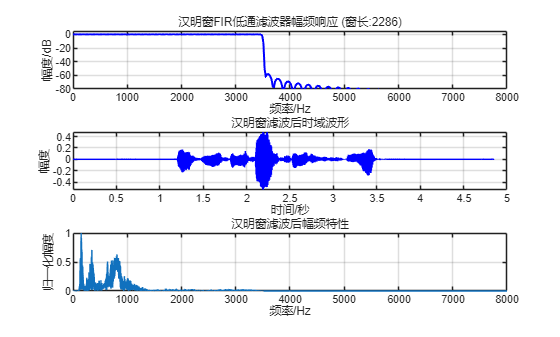

%% 要求：窗函数设计法FIR滤波器
clear; clc;
[y, Fs] = audioread('dspx1.wav');
n = length(y);
k = 0:n-1;

% 添加正弦噪声
f_noise = 4000; 
A_noise = 0.02; 
noise = A_noise * cos(2*pi*f_noise*k*(1/Fs));
y_noise = y + noise'; 
x = (0:n-1)*(1/Fs);
f = k*Fs/n;

% figure;
% 时域波形
% subplot(2,1,1);
% plot(x, y_noise);
% xlabel('时间/秒');
% ylabel('幅度');
% title('加噪信号时域波形');
% grid on;
% 频域波形
% Y_noise = fft(y_noise, N);
% subplot(2,1,2);
% plot(f, abs(Y_noise)/(max(abs(Y_noise))));
% xlabel('频率/Hz');
% ylabel('归一化幅度');
% title('加噪信号幅频特性');
% axis([0, 8000, 0, 1]);
% grid on;

fp = 3400;  % 通带截止频率
fs = 3600;  % 阻带起始频率
wp = fp*2*pi/Fs;  % 通带归一化频率
ws = fs*2*pi/Fs;  % 阻带归一化频率

N = (6.6*pi / (ws/pi-wp/pi));
N = ceil(N); % 向上取整
wc = (wp + ws) / 2;
wn = wc / pi;  % 归一化到0-1范围

b_hamming = fir1(N, wn, 'low', hamming(N+1));
[H_hamming, w_hamming] = freqz(b_hamming, 1, 1024, Fs);
H_hamming_db = 20*log10(abs(H_hamming)/max(abs(H_hamming)));
y_hamming = filter(b_hamming, 1, y_noise);
Y_hamming = fft(y_hamming, n);

figure;
% 滤波器幅频特性
subplot(3,1,1);
plot(w_hamming, H_hamming_db, 'b', 'LineWidth', 1.5);
xlabel('频率/Hz');
ylabel('幅度/dB');
title(['汉明窗FIR低通滤波器幅频响应 (窗长:', num2str(N), ')']);
grid on;
axis([0, 8000, -80, 5]);

% 滤波后信号时域波形
subplot(3,1,2);
plot(x, y_hamming, 'b');
xlabel('时间/秒');
ylabel('幅度');
title('汉明窗滤波后时域波形');
grid on;

% 滤波后信号频域特性
subplot(3,1,3);
plot(f, abs(Y_hamming)/max(abs(Y_hamming)));
xlabel('频率/Hz');
ylabel('归一化幅度');
title('汉明窗滤波后幅频特性');
axis([0, 8000, 0, 1]);
grid on;

% sound(y_noise, Fs); % 播放加噪后的音频
% sound(y_hamming, Fs); % 播放滤波后的音频